clear,clc, close all;
Ts = 0.001; % sec


m = 0.116527;     % pend mass (kg)
M = 0.28;     % cart mass (kg)
L = 0.30/2;    % pend's length from rotational hinge to center of gravity (m)
I = (1/3)*m*L^2;   % moment of inertia around center of gravity (kg.m2)
g = 9.80665;     % gravitational accel (m/s2)

uMax = 20;    % maximum input (m/s2)
x1_max = 0.43;% track limit (m)
x2_max = 1.8; % cart vel max (m/s)

E_up = m*g*L*cos(0);

% swing-up control params
k_su = 1;
k_cw = 5;
k_vw = 2.5;
k_em = 9;
eta  = 1.3;

% friction
kd = 0.000161;   % damping const (N.s/rad)
kdr = 0.000001; 
kt = 150;
Fc = 0.00040;

myData = readmatrix("data_encoder\system_data_3.csv");

myData = rmmissing(myData(:,3));
myData_unbias = myData - myData(1,:);
[max_val_unbias, idx_max] = max(abs(myData_unbias))

max_val_unbias = 1.1129

idx_max = 3836

myData = myData(idx_max:end,:);
shapeMyData = size(myData);
timeRange = ((linspace(1, shapeMyData(1), shapeMyData(1)) - 1).*Ts)'

timeRange =          0
    0.0010
    0.0020
    0.0030
    0.0040
    0.0050
    0.0060
    0.0070
    0.0080
    0.0090


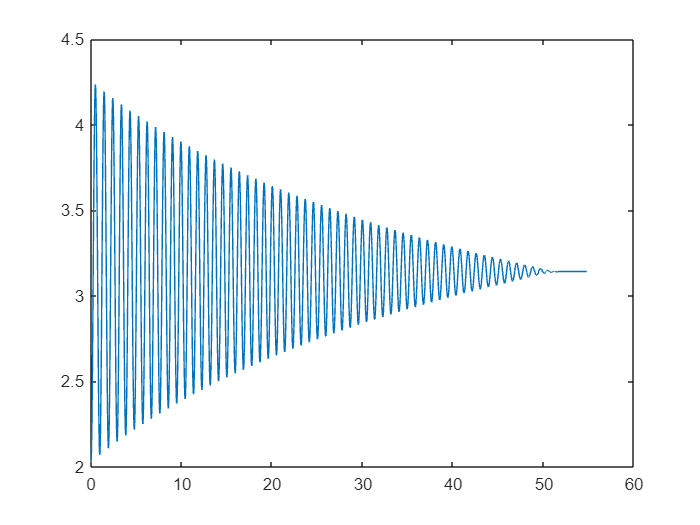

% myData = (myData + 4000) / 8000 * (2 * pi);
plot(timeRange, myData)

% simulation
data_to_simulink = [timeRange, myData];
init_angle = myData(1,:);
input_data = [timeRange, zeros(size(myData))];
mdl = "system_ID.slx";
% mdl = "derivative_test.slx";
open_system(mdl);